close all
clear all

% This code will drift correct the current scan data

addpath('pre_req scripts echo');
file_name = ['C:\Users\Mog\Desktop\dy010005']; % Expt file name (without the .dat)

[Iscan,counts,datavec,lam,spec_lamX] = read_current_scan_h2_new1([file_name,'.dat'],1,1,1,0);

PARAMETES OF H2


## All data - This section fits a polynomial through all of the data as one long continuous dataset

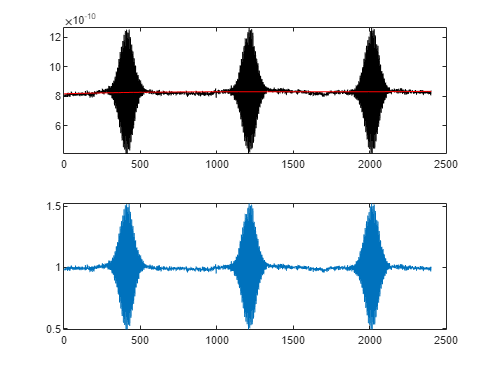

datavec_rs = reshape(datavec(:,:,1)',[1,size(datavec,1)*size(datavec,2)]); % Reshaping the data into a continuous list

xx = 1:length(datavec_rs); % Setting the x axis

fit_result = polyfit(xx,datavec_rs,3); % Fitting a polynomial to the data - to change the order of the polynomial change the number
fit = polyval(fit_result,xx); % Calculating the fit

figure 
subplot(2,1,1) % Showing the raw data and the fit
plot(xx,datavec_rs,'k')
hold on
plot(xx,fit,'r')
hold off

data_corr = datavec_rs./fit;

subplot(2,1,2) % Showing the drift corrected data
plot(xx,data_corr)

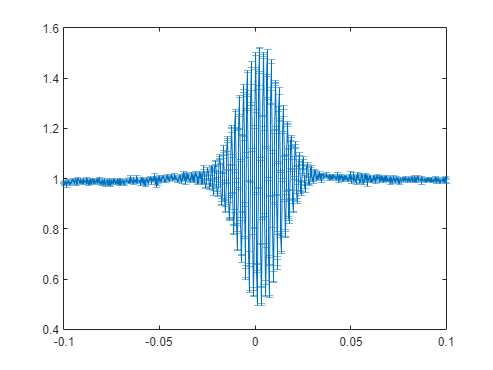


datavec_corr = reshape(data_corr,size(datavec,2),size(datavec,1));
datavec_corr = datavec_corr';

counts = mean(datavec_corr); % Working out the average signal (over all loops)
err = std(datavec_corr)/sqrt(size(datavec_corr,1)); % Working out the error for each point
sg_corr = datavec_corr; % This is the drift corrected loops individually

% This if statement is a fudge so that if there is only one loop and it
% can't calculate an error, it sets the error to be zero on all points
if size(datavec_corr,1) == 1;
    err = zeros(size(datavec_corr,2),1);
    counts = datavec_corr(1,:);
end

% Plotting the averaged data
figure
errorbar(Iscan,counts,err);


save([file_name,'_Iscan_counts_err_drift_corr.mat'],'Iscan','counts','err') % Saving the current, average signal and error
save([file_name,'_Iscan_sg_corr_drift_corr.mat'],'Iscan','sg_corr'); % Saving the current, and individual loops

## Loop - Does the same as the above but corrects each loop individually. Useful if the detector is going for a particularly bad walk!

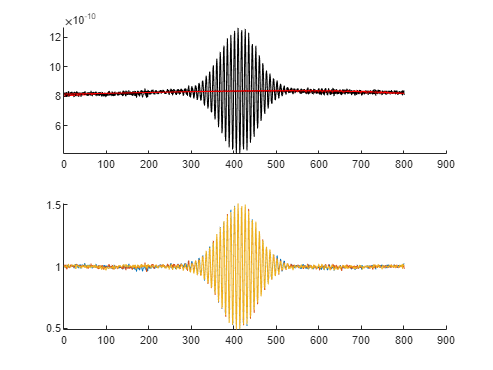

datavec_loop_corr = zeros(size(datavec));

figure 
subplot(2,1,1)
hold on
subplot(2,1,2)
hold on

for ii = 1:size(datavec,1);
    datav = datavec(ii,:,1);
    xx2 = 1:length(datav);
    
    fit_result = polyfit(xx2,datav,3); % Again if you want to change the degree of the polynomial, change that here
    fit = polyval(fit_result,xx2);
    
    subplot(2,1,1) % Plotting the loops and the fits (gets a bit messy if you have alot of loops!)
    plot(xx2,datav,'k')
    plot(xx2,fit,'r')
    
    data_corr_loop(ii,:) = datav./fit;

    subplot(2,1,2) % Plotting all the loops that have been drift corrected
    plot(xx2,data_corr_loop(ii,:)) 
end

subplot(2,1,1)
hold off
subplot(2,1,2)
hold off

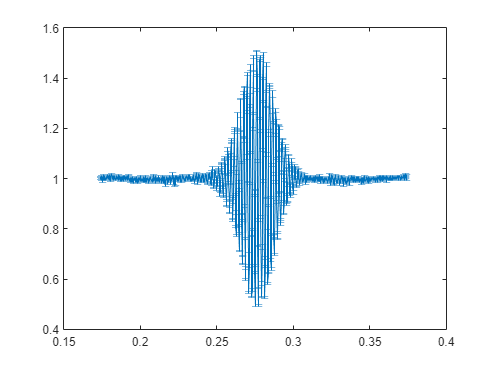


counts = mean(data_corr_loop); % Mean signal
err = std(data_corr_loop)/sqrt(size(data_corr_loop,1)); % Error
sg_corr = data_corr_loop; % Individual drift corrected loops

% Same as before if there is only one loop the error is zero
if size(datavec_corr,1) == 1;
    err = zeros(size(datavec_corr,2),1);
    counts = datavec_corr(1,:);
end

figure
errorbar(Iscan+0.2738,counts,err);


save([file_name,'_loop_Iscan_counts_err_drift_corr.mat'],'Iscan','counts','err') % Saving the current, average signal and error
save([file_name,'_loop_Iscan_sg_corr_drift_corr.mat'],'Iscan','sg_corr'); % Saving the current and individual drift corrected loops